# **Uninfected**

## **GLOBULOS BLANCOS**

### **a) Anotaciones**

close all; clc; clearvars;
% Cargar carpeta del 1º paciente
imageFolder='C:\Users\ASUS\Documents\3ºMondragon Universidad\6º Semestre\PBL 6\Procesamiento\Dataset\Uninfected\NIH-NLM-ThickBloodSmearsU\Uninfected Patients\TF201_HT6\tiled'; 

% Cargar imagenes del 1º paciente
imageFiles=dir(fullfile(imageFolder, '*.tiff'));

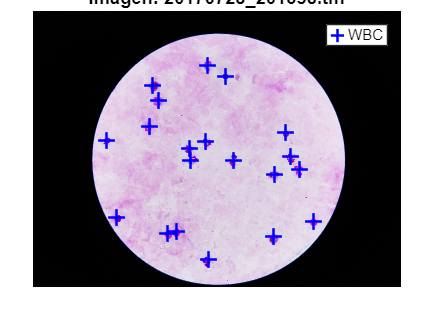

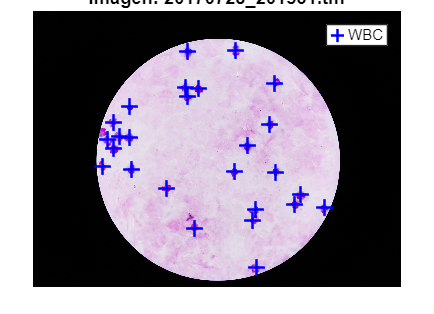

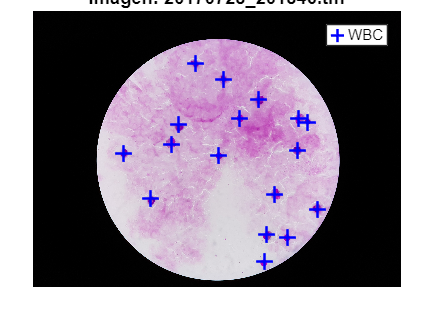

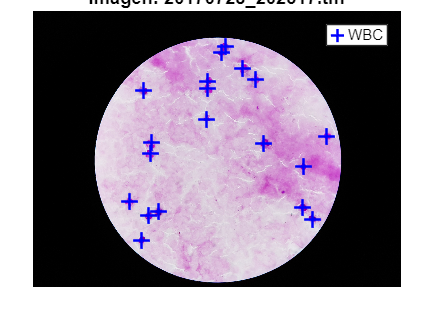

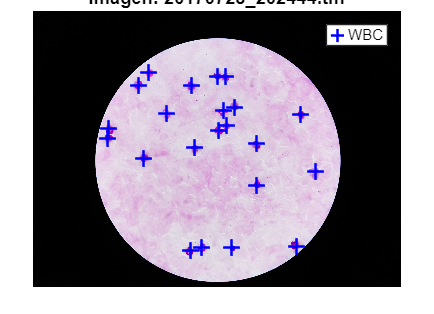

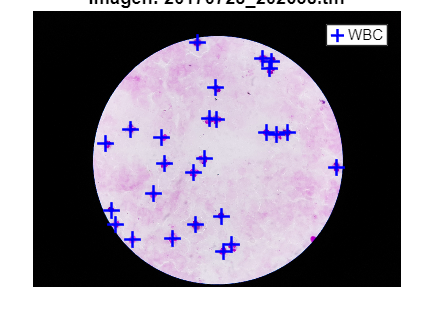

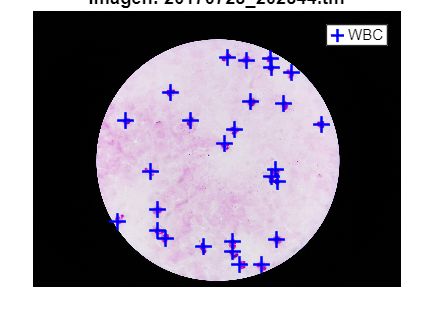

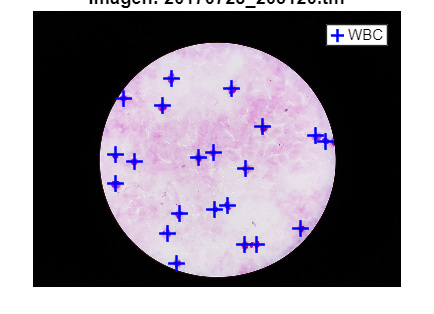

for i = 1:length(imageFiles)
    % Nombre completo del archivo
    filename=fullfile(imageFolder, imageFiles(i).name);

    % Cargar la imagen
    I=imread(filename);
    figure;
    imshow(I); hold on;

    % Carpetas de las anotaciones
    ruta_GT = fullfile('C:\Users\ASUS\Documents\3ºMondragon Universidad\6º Semestre\PBL 6\Procesamiento\Dataset\Uninfected\NIH-NLM-ThickBloodSmearsU\Annotations\TF201_HT6\results\2546', [imageFiles(i).name(1:end-5), '.txt']);
    
    % Datos de cada carpeta
    datos = readtable(ruta_GT, 'Delimiter', ',', 'HeaderLines', 1);

    % ===== GLÓBULOS BLANCOS =====
    solo_WBC = datos(strcmp(datos.Var2, 'White_Blood_Cell'), :);
    x_wbc = solo_WBC.Var6;
    y_wbc = solo_WBC.Var7;
    plot(x_wbc, y_wbc, 'b+', 'MarkerSize', 10, 'LineWidth', 1.5);  % cruces azules

    title(['Imagen: ', imageFiles(i).name], 'Interpreter', 'none');
    legend('WBC');
    hold off;
end

## **PARÁSITOS**

**No debería de haber**

### b) 1º Modelo K-means

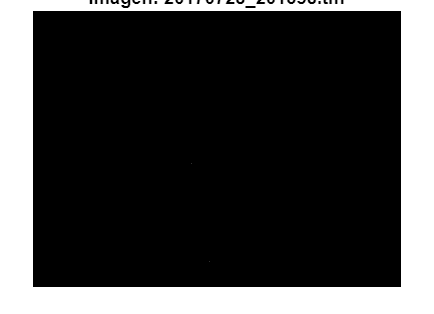

ruido = 4

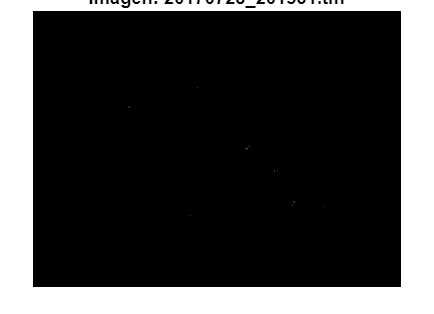

ruido = 18

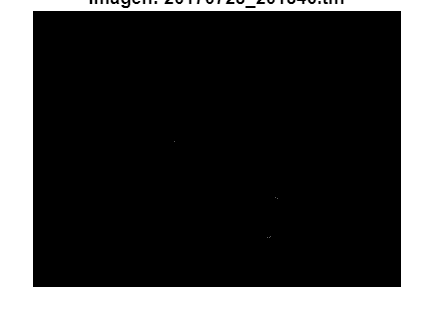

ruido = 16

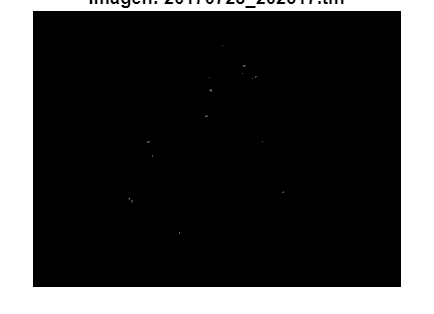

ruido = 23

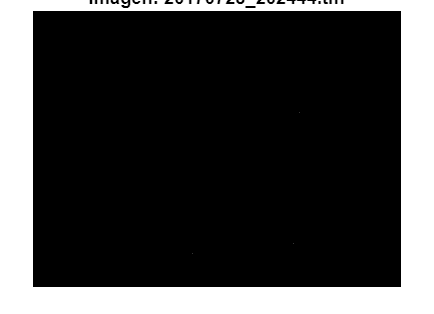

ruido = 8

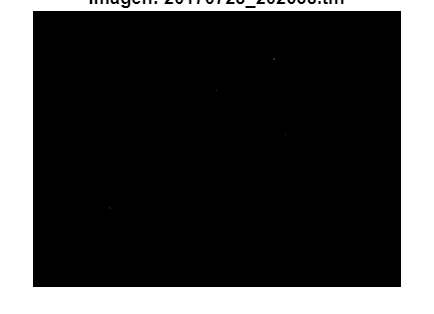

ruido = 15

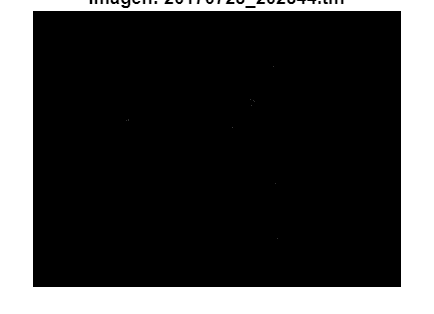

ruido = 16

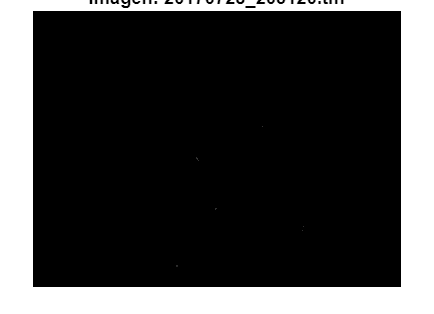

ruido = 9

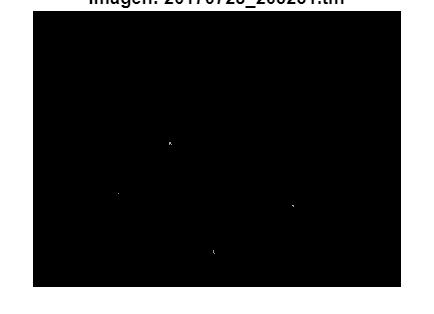

ruido = 8

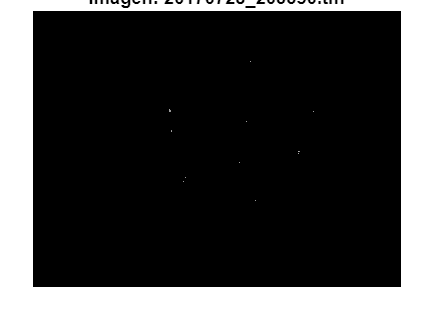

ruido = 26

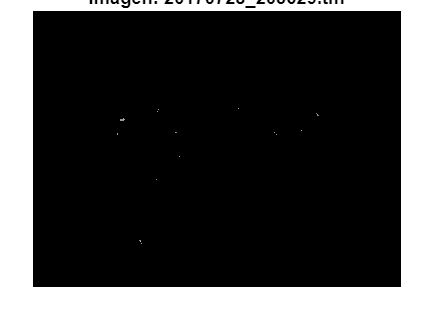

ruido = 25

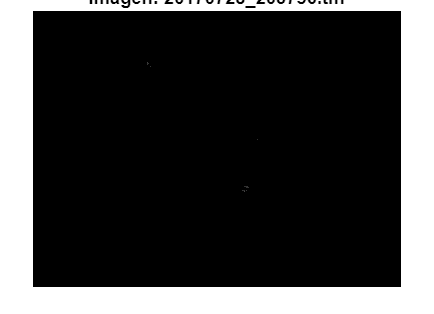

ruido = 7

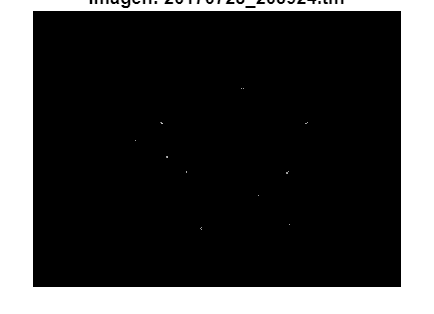

ruido = 24

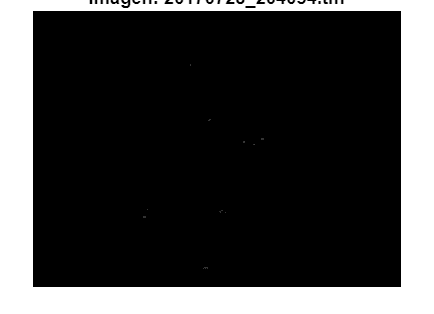

ruido = 19

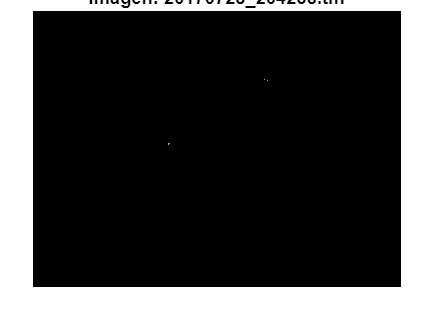

ruido = 8

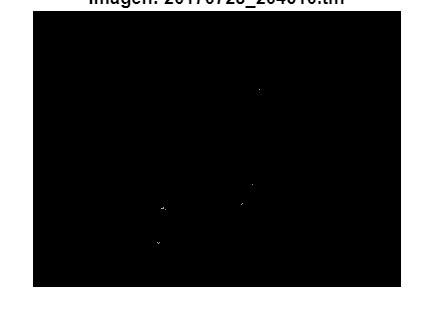

ruido = 23

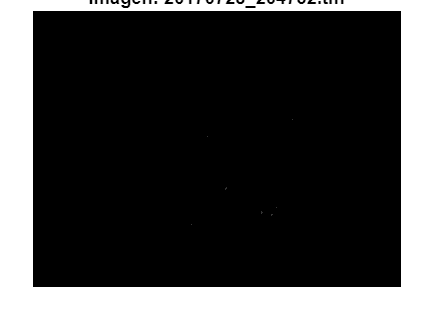

ruido = 12

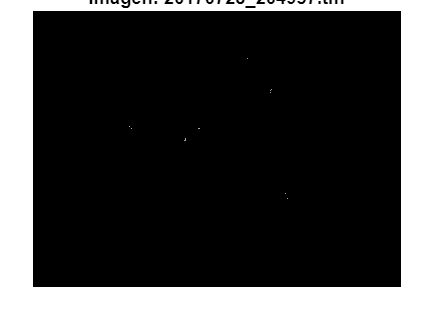

ruido = 25

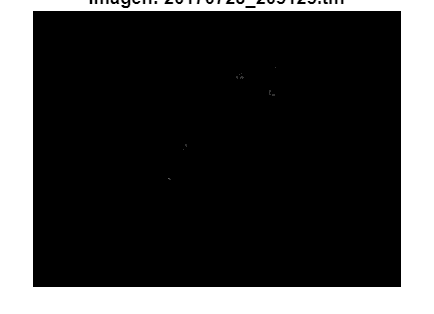

ruido = 20

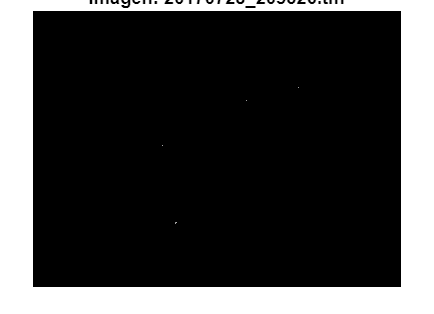

ruido = 12

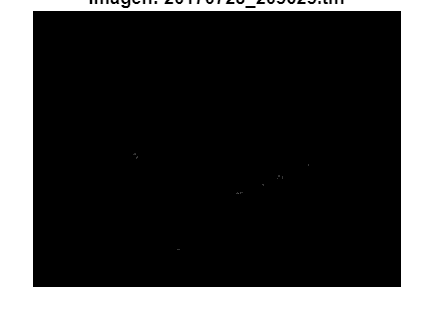

ruido = 18

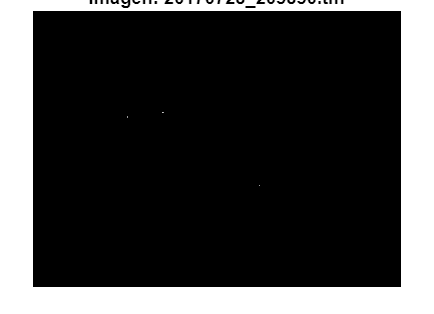

ruido = 11

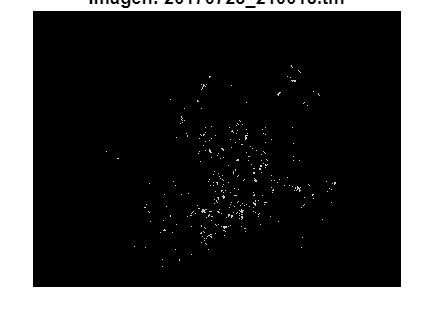

ruido = 779

total_ruido=0;
cantidad_imagenes_ruido=0;
for i = 1:length(imageFiles)
    % Fitxategiaren izen osoa
    filename=fullfile(imageFolder, imageFiles(i).name);

    % Cargar la imagen
    I=imread(filename);
    
    % Binario y escala de grises
    I_gray=im2double(rgb2gray(I));
    
    % Filtro
    I_sinruido=medfilt2(I_gray, [3 3]);
  
    % === K-means para segmentar ===
    I_reshape = reshape(I_sinruido, [], 1);
    [cluster_idx, cluster_centers] = kmeans(double(I_reshape), 3);
    segmented_image = reshape(cluster_idx, size(I_sinruido));
    dark_points_mask = segmented_image == min(segmented_image(:));  % zonas oscuras
    
    % === Glóbulos blancos sin ruido ===
    WBC_mask = bwareaopen(dark_points_mask, 500);
    
    parasite_candidate_mask = dark_points_mask & ~WBC_mask;  % quitar glóbulos blancos
    
    se = strel('disk', 2);  % Estructura de dilatación
    dilated_parasites = imdilate(parasite_candidate_mask, se);
    
    % === Preprocesar para detectar parásitos ===
    parasite_candidate_mask = imfill(dilated_parasites, 'holes');
    parasite_candidate_mask = imopen(dilated_parasites, strel('disk',1));
    
    % === Usar como máscara en la imagen original (opcional) ===
    mascara_parasitos = I_gray;
    mascara_parasitos(~dilated_parasites) = 0;  % fondo negro

    % Visualiza la máscara final
    figure;
    imshow(mascara_parasitos);
    title(['Imagen: ', imageFiles(i).name], 'Interpreter', 'none');
    
    % Mirar las propiedades de los pixeles
    n=8; % neighbourhood

    % Contar puntos detectados
    CC = bwconncomp(mascara_parasitos,n);
    properties = {'Centroid', 'Circularity', 'Area','Eccentricity', 'Solidity'};
    caracteristicas = regionprops(CC,properties);
    ruido=size(caracteristicas,1)
    total_ruido=total_ruido+ruido;
    if ruido>=1
        cantidad_imagenes_ruido=cantidad_imagenes_ruido+1;
    end
end

total_ruido

total_ruido = 1126

cantidad_imagenes=length(imageFiles)

cantidad_imagenes = 23

media=total_ruido/cantidad_imagenes

media = 48.9565